

s.Terminator = {'LF','LF/CR'};

% read all chars in the buffer
fgets__ = @(s)char(fread(s,s.BytesAvailable))';

% send cmd like following
fprintf(s,'*IDN?'); 

% get reply form laser
backInfo = fgets__(s);


'*IDN?'

Gets the laser's identification string 

'*RST'

Causes a device to warm boot If Implemented

'*TST?'

Runs a laser self test procedure, if implemented 

'SYSTem:STATus?'

Queries the system status

bitNum = find(hex2poly(cell2mat(regexp(backInfo,'[0-9]+','match')),'as'))-1;

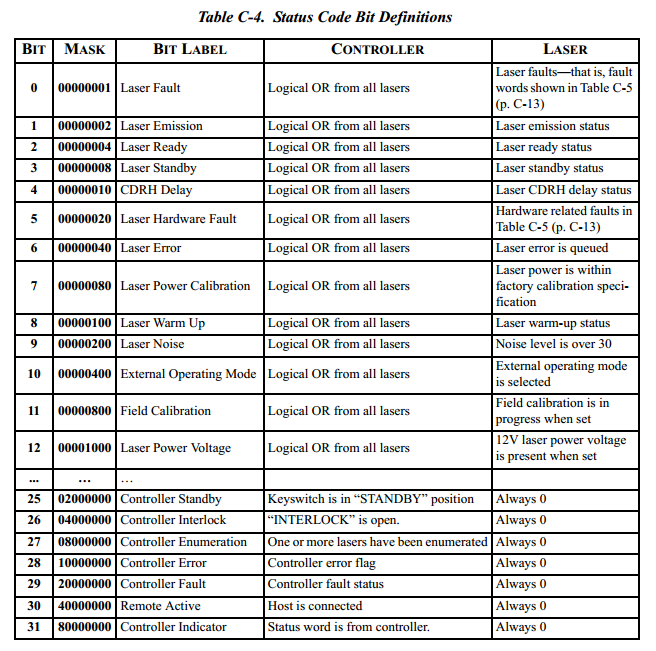

'SYSTem:FAULt?'

Queries current system faults 

'SYSTem:ERRor:COUNt?'

Queries the number Of error records in the error queue

'SYSTem:ERRorNEXT?'

 Queries the next error record(s) in the error queue 

'SYSTem:ERRorCLEar'

 Clears all error records in the error queue 

'SOURce:POWer:LIMit:LOW?'

Returns the mimmum CW laser output power 

'SOURce:POWer:LIMit:HIGH?'

Returns the maximum CW laser output power

'SOURce:POWer:LEVel?'

Returns the present output power of the laser 

'SOURce:POWer:CURRent?'

Returns the present output current of the laser 

'SOURce:POWer:LEVel:IMMediate:AMPLitude?'

Returns the present output current of the laser 

'SOURce:POWer:LEVel:IMMediate:AMPLitude 0.00500'

Sets present laser power level at W

'SOURce:AM:STATe ON'

'SOURce:AM:STATe OFF'

Turns the laser ON or OFF 

'SOURce:AM:STATe?'

Queries the current laser emlsslon status